clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = ".png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "./tex/images/";
% addpath("../CVX-arm64/");
% cvx_setup;
mkdir(SAVE_DIR);

T = 0.5;
a = 1.8;
b = 7.7;
zeta = 0.69;
omega_d = 5;
K_nu = 0.1;

HG_cont = tf([0.02564, 0.09615], [1, -0.8782]);
ss(HG_cont)

ans =
 
  A = 
           x1
   x1  0.8782
 
  B = 
         u1
   x1  0.25
 
  C = 
           x1
   y1  0.4747
 
  D = 
            u1
   y1  0.02564
 
Continuous-time state-space model.
Model Properties


## Task 1

T1 = 1;
G = tf([1], [b, 1], 'InputDelay', a);
% G = tf([1], [b, 1]);
% c2d(G, T1, 'zoh')
HG_no_delay = tf([0.02564, 0.09615], [1, -0.8782], T1);
% HG_no_delay = c2d(G, T1, 'zoh');
HG_delay = tf([1], [1, 0, 0], T1);
HG_delay * HG_no_delay, pole(HG_delay * HG_no_delay), ss(G)

ans =
 
  0.02564 z + 0.09615
  -------------------
   z^3 - 0.8782 z^2
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


ans =          0
         0
    0.8782


ans =
 
  A = 
            x1
   x1  -0.1299
 
  B = 
        u1
   x1  0.5
 
  C = 
           x1
   y1  0.2597
 
  D = 
       u1
   y1   0
 
  Input delays (seconds): 1.8 
 
Continuous-time state-space model.
Model Properties


H_d1 = tf([1], [1, 0, 0, 0], T1)

H_d1 =
 
   1
  ---
  z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


C1 = (H_d1 / (1 - H_d1)) / (HG_no_delay * HG_delay)

C1 =
 
                    z^6 - 0.8782 z^5
  -----------------------------------------------------
  0.02564 z^7 + 0.09615 z^6 - 0.02564 z^4 - 0.09615 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


sim_res = sim("task1.slx", 5);
clf;
title("System output");
hold on;
stairs(sim_res.y.time, sim_res.y.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.T.time, sim_res.T.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--');
grid on;
legend({'y', 'step(T_d)'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task1_y" + SAVE_EXT);

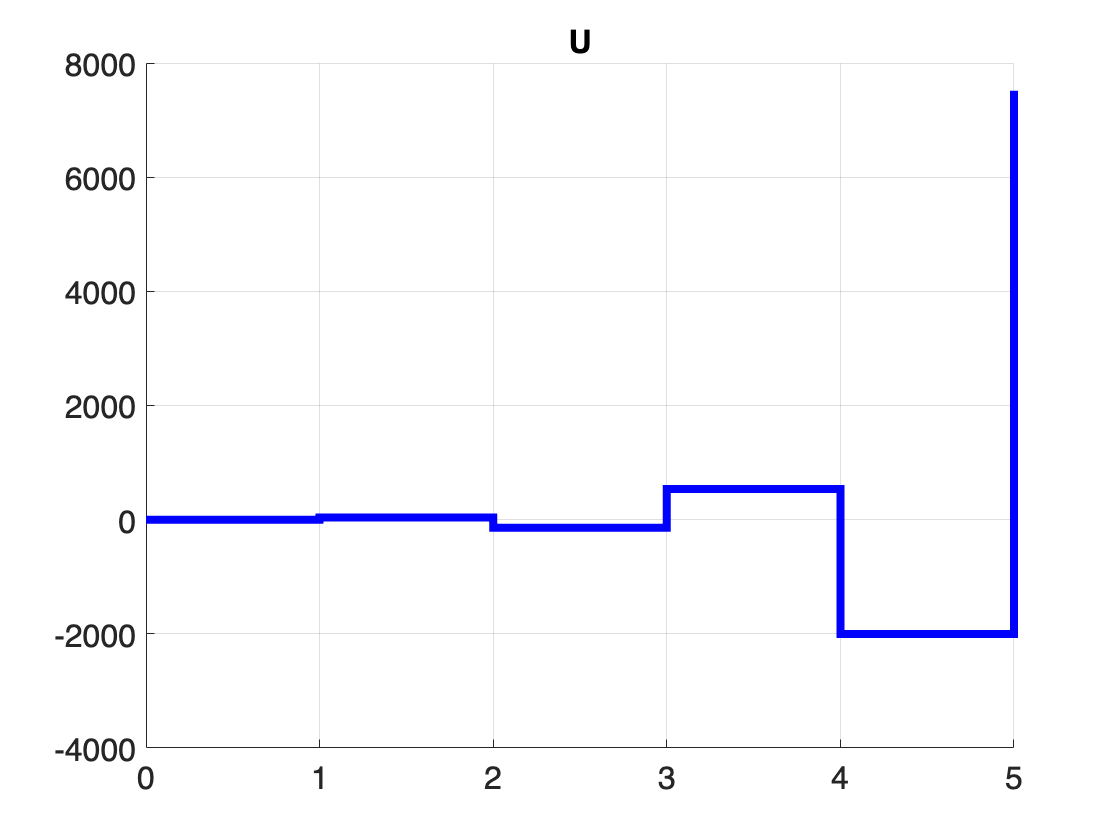

clf;
title("U");
hold on;
stairs(sim_res.y.time, sim_res.u.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
grid on;
% legend({'y', 'T'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task1_u" + SAVE_EXT);

pole(C1), zero(C1)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -3.7500 + 0.0000i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i
   1.0000 + 0.0000i


ans =          0
         0
         0
         0
         0
    0.8782


## **Task 2**

q = 1;
e_Tc = exp(-T1 / q);
H_d2 = tf([1 - e_Tc], [1, -e_Tc], T1) * H_d1

H_d2 =
 
       0.6321
  ----------------
  z^4 - 0.3679 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


C2 = (H_d2 / (1 - H_d2)) / HG_no_delay / HG_delay

C2 =
 
                               0.6321 z^7 - 0.7877 z^6 + 0.2042 z^5
  -----------------------------------------------------------------------------------------------
  0.02564 z^9 + 0.07729 z^8 - 0.06727 z^7 + 0.01301 z^6 - 0.01621 z^5 - 0.05482 z^4 + 0.02236 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


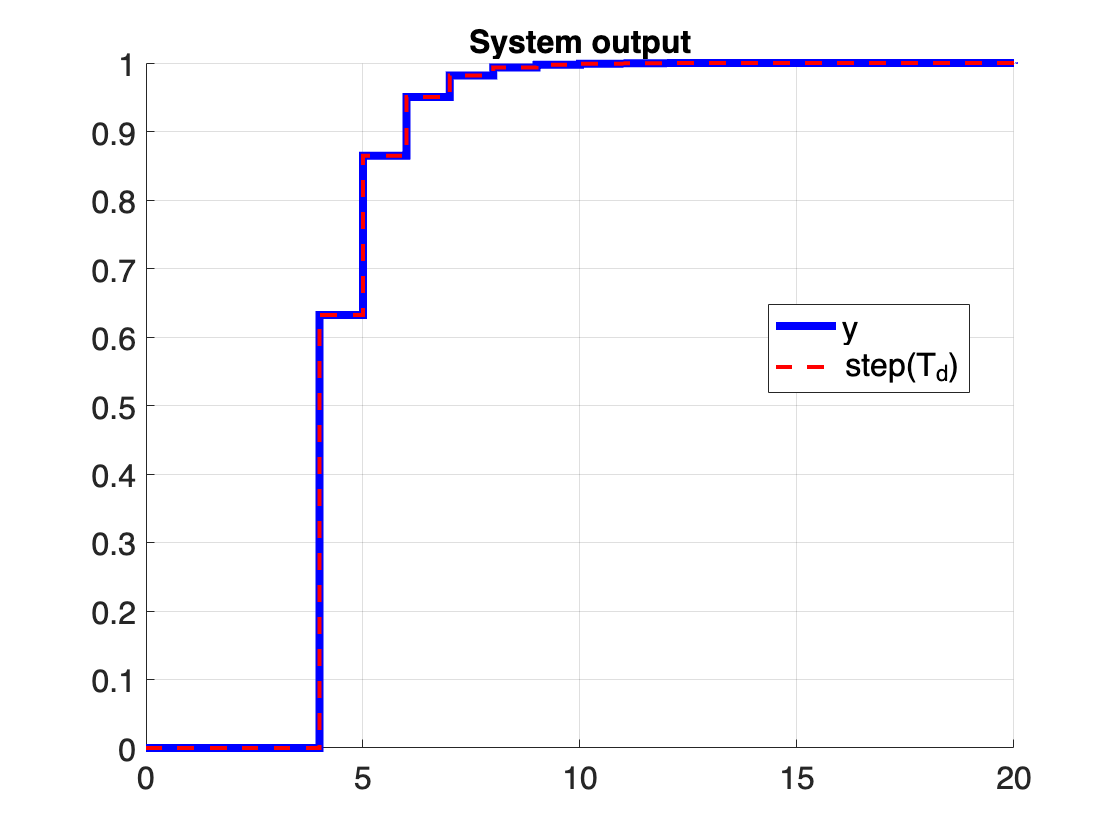

sim_res2 = sim("task2.slx", 20);
clf;
title("System output");
hold on;
stairs(sim_res2.y.time, sim_res2.y.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res2.T.time, sim_res2.T.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--');
grid on;
legend({'y', 'step(T_d)'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_y" + SAVE_EXT);

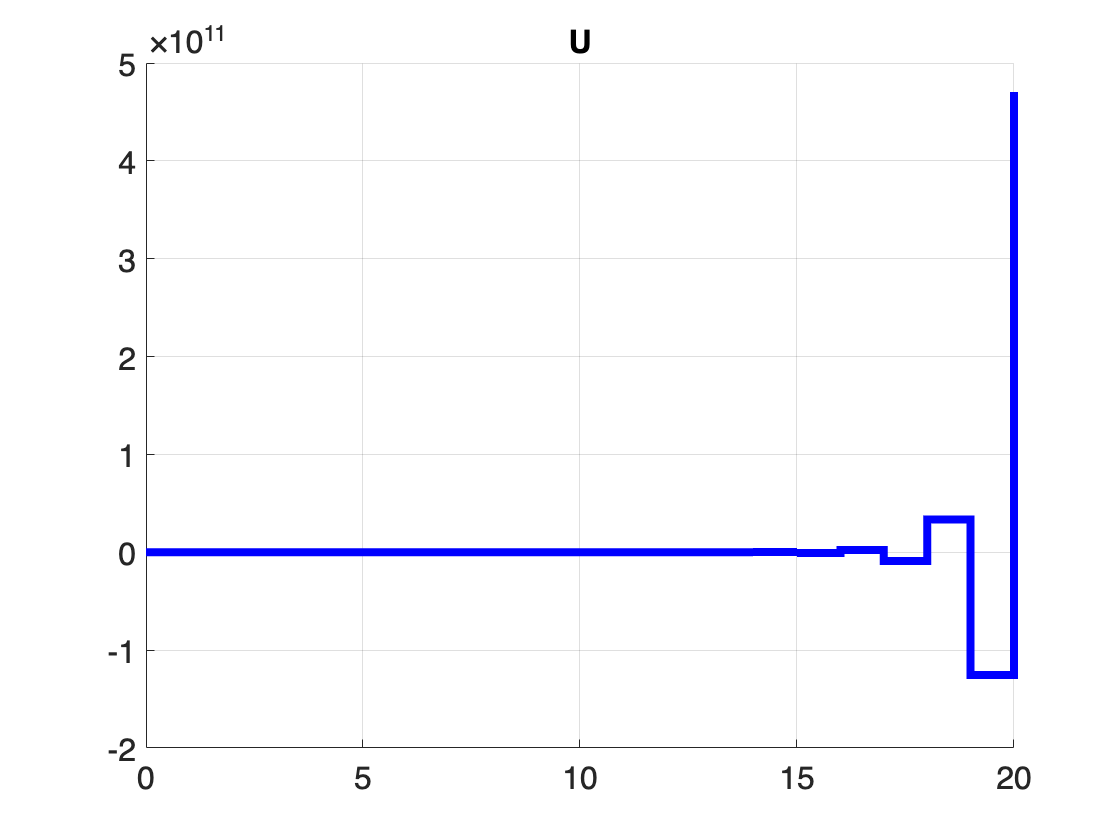

clf;
title("U");
hold on;
stairs(sim_res2.y.time, sim_res2.u.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
grid on;
% legend({'y', 'T'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_u" + SAVE_EXT);

pole(C2)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -3.7500 + 0.0000i
  -0.8121 + 0.0000i
   0.0900 + 0.8776i
   0.0900 - 0.8776i
   1.0000 + 0.0000i
   0.3679 + 0.0000i


Задание 3

z1 = exp(-zeta * omega_d * T) *(cos(omega_d * T * sqrt(1 - zeta^2)) +  j * sin(omega_d * T * sqrt(1 - zeta^2)))

z1 = -0.0421 + 0.1731i

z2 = exp(-zeta * omega_d * T) *(cos(omega_d * T * sqrt(1 - zeta^2)) - j * sin(omega_d * T * sqrt(1 - zeta^2)))

z2 = -0.0421 - 0.1731i

b_1 = -24.4029204000002 

b_1 = -24.4029

b_2 = 25.5188564200002

b_2 = 25.5189

Td_3 = tf([b_1, b_2], [1, 0.0842, 0.03173602], T);
HG_3 = tf([0.03, 0.03 * 0.75], [1, -1.5, 0.5], T);

C_3 = 1 / HG_3 * Td_3 / (1 - Td_3)

C_3 =
 
   -24.4 z^5 + 60.07 z^4 - 46.02 z^3 + 10.48 z^2 - 0.5277 z + 0.4049
  -------------------------------------------------------------------
  0.03 z^5 + 0.7596 z^4 - 0.149 z^3 - 0.5674 z^2 - 0.05507 z - 0.0182
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


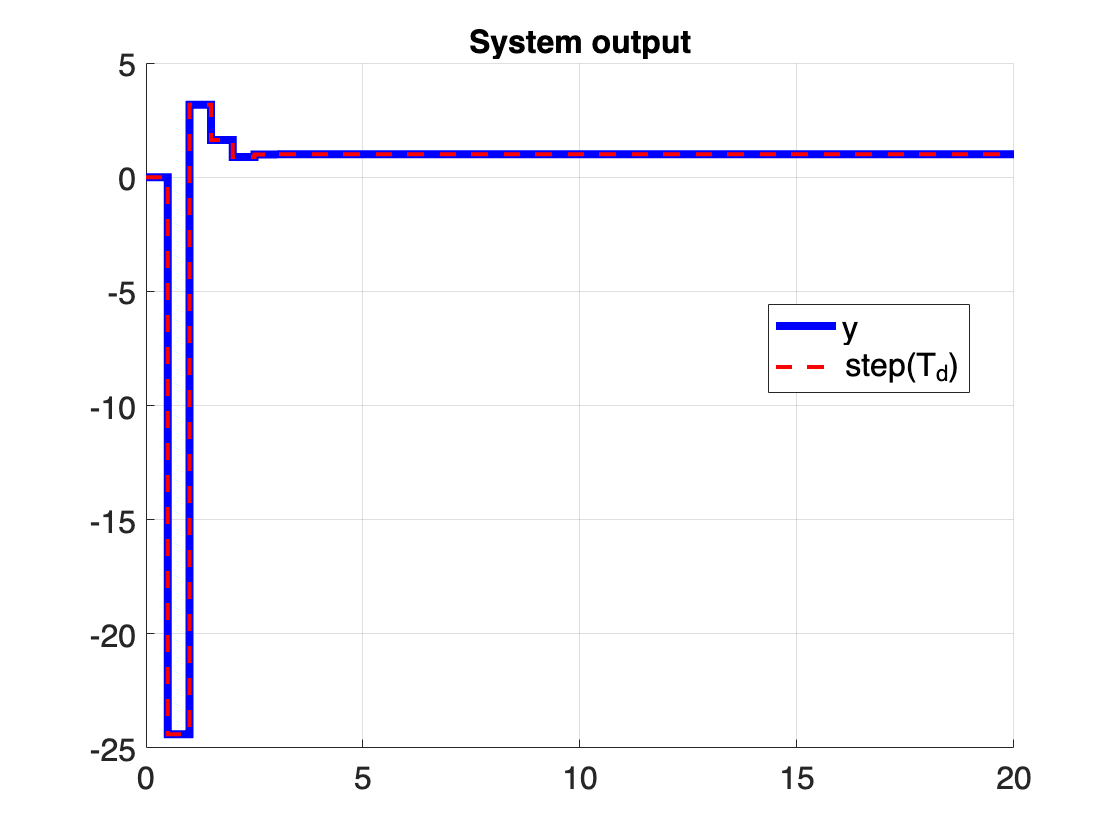

sim_res3 = sim("task3.slx", 20);
clf;
title("System output");
hold on;
stairs(sim_res3.y.time, sim_res3.y.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res3.T.time, sim_res3.T.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--');
grid on;
legend({'y', 'step(T_d)'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_y" + SAVE_EXT);

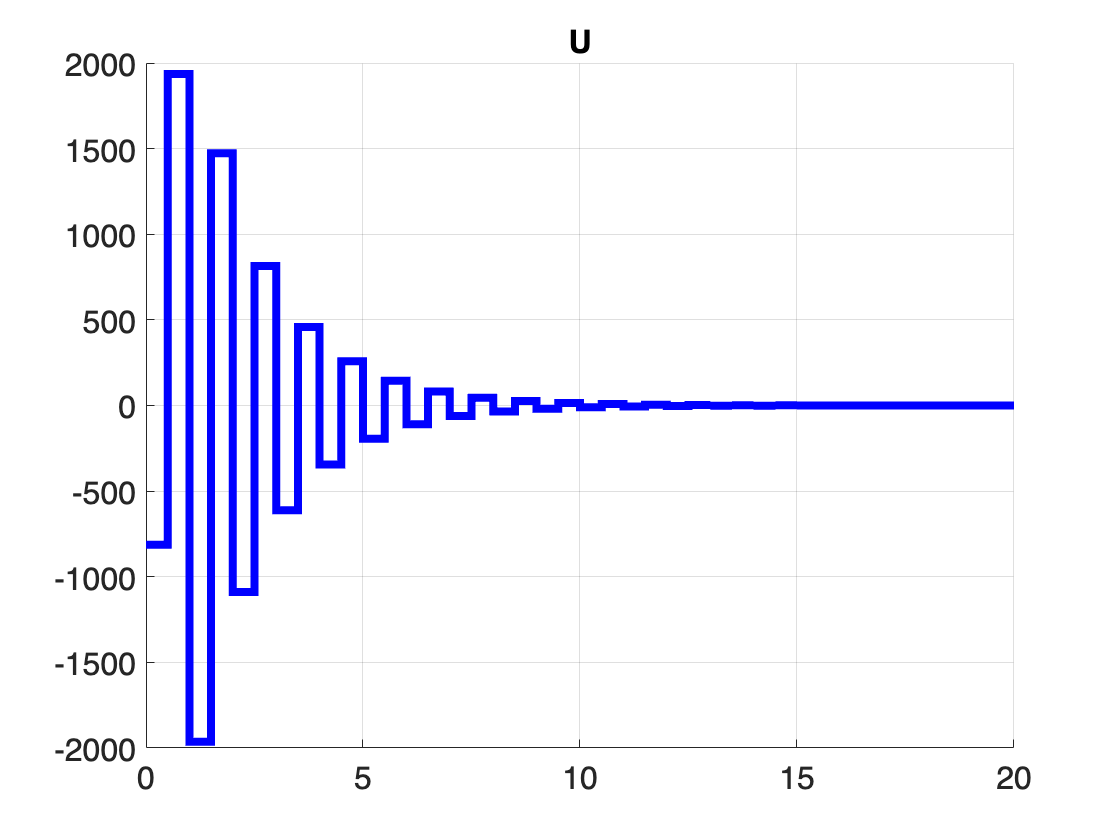

clf;
title("U");
hold on;
stairs(sim_res3.u.time, sim_res3.u.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
grid on;
% legend({'y', 'step(T_d)'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_u" + SAVE_EXT);